# LCE

## 20250516 运放验证

%% AC Gain 数据处理

clc, clear, close all
data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[op amp] ac gain, discrete uA741, input 1 Vamp, 10 nF + 51 kOhm.txt");
V_in = data(:, 4)';
V_out = data(:, 5)';
f = data(:, 1)';
phase = - data(:, 2)';
phase = MyFilter_mean(phase, 3);

num_filt = 350;
phase(num_filt:end) = MyFilter_mean(phase(num_filt:end), 20);
V_in(num_filt:end) = MyFilter_mean(V_in(num_filt:end), 5);
V_out(num_filt:end) = MyFilter_mean(V_out(num_filt:end), 5);

A_v = (1+(1./(2*pi*f*10^(-8))+51000)/100) .* (V_out./V_in);
A_v_dB = 20*log(A_v)/log(10);

stc = MyYYPlot(f, f, A_v_dB, phase);
stc.axes.XScale = 'log';
stc.leg.String = ["Gain $A_v$ (dB)"; "Phase $\varphi\ (^\circ)$"];
stc.label.x.String = 'Frequency $f$';
stc.label.y_left.String = 'Open-Loop Small-Signal Gain $A_v$ (dB)';
stc.label.y_right.String = 'Output Phase Shift $\varphi\ (^\circ)$';
MyFigure_ChangeSize_2048x512
ylim([0 80])
xlim([2e2, 2e5])
stc.axes.XTick = [2e2, 1e3, 2e3, 1e4, 2e4, 1e5, 2e5]

stc = 包含以下字段的 struct :
        fig: [1×1 Figure]
       axes: [1×1 Axes]
     p_left: [1×1 Line]
      label: [1×1 struct]
    p_right: [1×1 Line]
        leg: [1×1 Legend]


stc.axes.XTickLabel = ["200 Hz", "1 kHz", "2 kHz", "10 kHz", "20 kHz", "100 kHz", "200 kHz"];
yyaxis('right')
ylim([0 180])
YTick = 0:22.5:180;
stc.axes.YTick = YTick

stc = 包含以下字段的 struct :
        fig: [1×1 Figure]
       axes: [1×1 Axes]
     p_left: [1×1 Line]
      label: [1×1 struct]
    p_right: [1×1 Line]
        leg: [1×1 Legend]


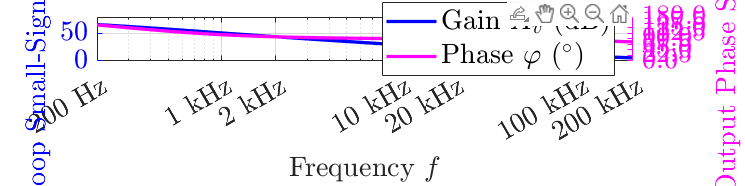

stc.axes.YTickLabel =  num2str(YTick', '%.1f');

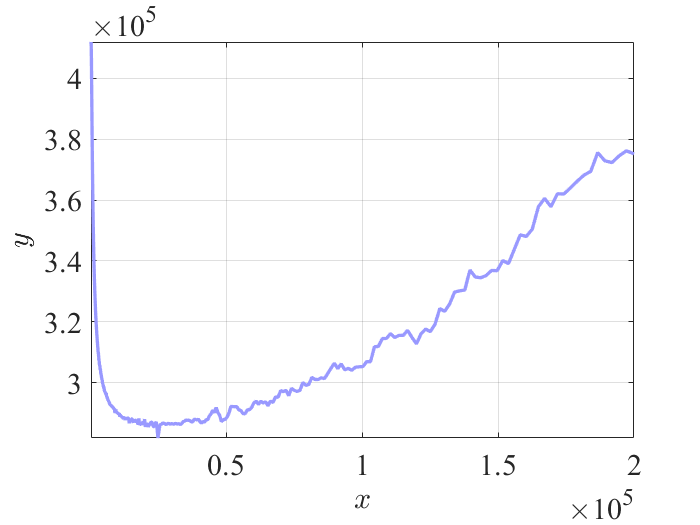

ans = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]



MyPlot(f, A_v.*f)

% 运放测量板测量运放参数
R_7 = 3.9e3;
R_77 = 390e3;
R_6 = 3.9e3;
R_66 = 390e3;



TP1_Vos = 3.5334;  % V_IO
TP2_Vos = 13.579e-3;
TP1_Ib_R7 = 3.3392;
TP1_Ib_R6 = 3.6214;
TP1_DCGain = 4.797;
TP2_DCGain = -8.0405;
TP1_DCGain_2 = 3.9408;
TP2_DCGain_2 = -3.9738;
TP1_PSRR = 3.3278;
Delta_Vs = 2*(16 - 12);


I_B_neg = -(TP1_Ib_R7 - TP1_Vos)/(R_7*1001);
I_B_neg_2 = -(3.4266 - 3.5654)/(R_7*1001);
I_B_pos = (TP1_Ib_R6 - TP1_Vos)/(R_6*1001);
I_B_pos_2 = (3.72 - 3.5566)/(R_6*1001);
A_v_dc = abs( 1001 * (TP2_DCGain - TP2_Vos) / (TP1_DCGain - TP1_Vos));
A_v_dc_2 = abs( 1001 * (TP2_DCGain_2 - TP2_Vos) / (TP1_DCGain_2 - TP1_Vos));
PSRR_dc = abs( 1001 * Delta_Vs / (TP1_PSRR - TP1_Vos) );


disp(['V_IO = ', num2str(TP1_Vos/1001 * 1000), ' mV'])

V_IO = 3.5299 mV


disp(['I_B_neg = ', num2str(I_B_neg*10^9), ' nA'])

I_B_neg = 49.7451 nA


disp(['I_B_neg_2 = ', num2str(I_B_neg_2*10^9), ' nA'])

I_B_neg_2 = 35.5542 nA


disp(['I_B_pos = ', num2str(I_B_pos*10^9), ' nA'])

I_B_pos = 22.5416 nA


disp(['I_B_pos_2 = ', num2str(I_B_pos_2*10^9), ' nA'])

I_B_pos_2 = 41.8556 nA


I_B = 0.5*(I_B_pos_2 + I_B_neg_2)*10^9

I_B = 38.7049

I_OS = 0.5*(I_B_pos_2 - I_B_neg_2)*10^9

I_OS = 3.1507


disp(['DC Gain 1 = ', num2str(A_v_dc), ' = ', num2str(20*log(A_v_dc)/log(10)), ' dB'])

DC Gain 1 = 6380.2889 = 76.0968 dB


A_v_dc_2

A_v_dc_2 = 9.7972e+03

disp(['DC Gain 2 = ', num2str(A_v_dc_2), ' = ', num2str(20*log(A_v_dc_2)/log(10)), ' dB'])

DC Gain 2 = 9797.1683 = 79.822 dB


disp(['DC PSRR = ', num2str(PSRR_dc), ' = ', num2str(20*log(PSRR_dc)/log(10)), ' dB'])

DC PSRR = 38949.4163 = 91.81 dB



GBWP = 2.051e3* 199.4;
disp(['GBWP = ', num2str(GBWP/10^6), ' MHz'])

GBWP = 0.40897 MHz


% square wave generator 计算
V_OH = 11.5;
V_OL = -10.5;
R_k = 10e3;
R_2 = 10e3;
V_D = 0.6004;
R_f = 10e3;
R_1 = 10e3;
C = 10e-9;

tau_1 = (R_k + R_2)*C

tau_1 = 2.0000e-04

tau_2 = R_2*C

tau_2 = 1.0000e-04

%tau_2 = tau_1

%t_1 =  tau_1 * log(  ( V_OH - V_OL/2 ) / ( V_OH/2 ) )
t_1 = tau_1 * log(  ( V_OH - V_OL/(1 + R_1/R_f) ) / ( V_OH/(1 + R_1/R_f) ) )

t_1 = 2.1384e-04

t_2 = tau_2 * log(  ( (V_OL + V_D) - V_OH/(1 + R_1/R_f) ) / ( (V_OL + V_D)/((1 + R_1/R_f)) ) )

t_2 = 1.1511e-04


T = t_1 + t_2

T = 3.2895e-04

f = 1/T

f = 3.0400e+03

% square wave generator 计算 (短路 D 和 R_k)
V_OH = 11.5;
V_OL = -10.5;
R_k = 0;
R_2 = 10e3;
V_D = 0;
R_f = 10e3;
R_1 = 10e3;
C = 10e-9;

tau_1 = (R_k + R_2)*C

tau_1 = 1.0000e-04

tau_2 = R_2*C

tau_2 = 1.0000e-04

%tau_2 = tau_1

%t_1 =  tau_1 * log(  ( V_OH - V_OL/2 ) / ( V_OH/2 ) )
t_1 = tau_1 * log(  ( V_OH - V_OL/(1 + R_1/R_f) ) / ( V_OH/(1 + R_1/R_f) ) )

t_1 = 1.0692e-04

t_2 = tau_2 * log(  ( (V_OL + V_D) - V_OH/(1 + R_1/R_f) ) / ( (V_OL + V_D)/((1 + R_1/R_f)) ) )

t_2 = 1.1299e-04


T = t_1 + t_2

T = 2.1991e-04

f = 1/T

f = 4.5474e+03

% https://www.allaboutcircuits.com/technical-articles/op-amp-and-transistor-analog-square-wave-oscillator-design/
V_OH = 5;
V_OL = -5;
R_k = 0;
R_2 = 1e3;
V_D = 0;
R_f = 10e3;
R_1 = 10e3;
C = 1e-6;

tau_1 = (R_k + R_2)*C

tau_1 = 1.0000e-03

tau_2 = R_2*C

tau_2 = 1.0000e-03

%tau_2 = tau_1

%t_1 =  tau_1 * log(  ( V_OH - V_OL/2 ) / ( V_OH/2 ) )
t_1 = tau_1 * log(  ( V_OH - V_OL/(1 + R_1/R_f) ) / ( V_OH/(1 + R_1/R_f) ) )

t_1 = 0.0011

t_2 = tau_2 * log(  ( (V_OL + V_D) - V_OH/(1 + R_1/R_f) ) / ( (V_OL + V_D)/((1 + R_1/R_f)) ) )

t_2 = 0.0011


T = t_1 + t_2

T = 0.0022

f = 1/T

f = 455.1196

C = 10e-9;
T = C*(  2*10 + 10 )*10^3 * log(1 + 2*10/10)

T = 3.2958e-04

f = 1/T

f = 3.0341e+03

k = 1 / ( 1 + (10 + 5)/(10 + 10) )

k = 0.5714

V_OH = 11.5;
V_OL = -10.5;
R = (2*10 + 10) * 10^3;
C = 10e-9;
T = -2*R*C*log( V_OH*(1-0.5) / (V_OH - V_OL*0.5) )

T = 6.4152e-04

f = 1/T

f = 1.5588e+03

T = 2*40e3*C*log( 2 + 1 )

T = 8.7889e-04

f = 1/T

f = 1.1378e+03

## 20250513 uA741 理论计算

% 1st stage
V_AN = 100;
V_AP = 70;
I_C = 13e-6;
V_T = 26e-3;
R_E = 1e3;

r_ON = V_AN/I_C

r_ON = 7.6923e+06

r_OP = V_AP/I_C

r_OP = 5.3846e+06

g_mN = I_C/V_T

g_mN = 5.0000e-04

g_mP = I_C/V_T

g_mP = 5.0000e-04


G_m1 = MyParallel(g_mN, g_mP)

G_m1 = 2.5000e-04

G_m1*1000

ans = 0.2500

R_1 = r_OP + (1+g_mP*r_OP)/g_mN;
R_2 = r_ON + (1 + g_mN*r_ON)*R_E;
R_out1 = MyParallel(R_1, R_2)

R_out1 = 5.5711e+06

A_v1 = G_m1 * R_out1

A_v1 = 1.3928e+03


% 2nd stage
beta = 100;
I_C = 0.7e-3;
g_m2 = I_C/V_T

g_m2 = 0.0269

r_pi2 = beta/g_m2

r_pi2 = 3.7143e+03

r_O2 = V_AN/I_C

r_O2 = 1.4286e+05

r_O4 = V_AP/I_C

r_O4 = 100000


beta_Eq = beta*(beta + 2)

beta_Eq = 10200

g_m_eq = g_m2/2

g_m_eq = 0.0135

r_O_eq = (V_AN/V_T)/(beta - 1)*r_pi2 + r_O2

r_O_eq = 2.8716e+05

r_pi_eq = 2*beta*r_pi2

r_pi_eq = 7.4286e+05

R_E = 51;

G_m2 = 1 / (R_E + MyParallel(1/g_m_eq, r_O_eq))

G_m2 = 0.0080

G_m2*1000

ans = 7.9830

R_out2 = MyParallel( r_O4, r_O_eq + (1 + g_m_eq*r_O_eq)*MyParallel(R_E, r_pi_eq) )

R_out2 = 8.2887e+04

A_v2 = G_m2*R_out2

A_v2 = 661.6825

R_in = r_pi_eq + R_E * (beta_Eq*r_O_eq + r_O_eq + r_O4) / (R_E + r_O_eq + r_O4)

R_in = 1.1287e+06


% overall
A_v = A_v1*R_in/(R_in + R_out1)*A_v2

A_v = 1.5525e+05

A_v_dB = 20*log(A_v)/log(10)

A_v_dB = 103.8209


% input resistance
I_C = 13e-6;
r_pi = beta*V_T/I_C

r_pi = 2.0000e+05

R_L = R_1

R_L = 1.0771e+07

R_emit_Q10 = (1 + R_L/r_OP) * MyParallel( r_pi / (beta + 1 + R_L/r_OP), r_OP )

R_emit_Q10 = 5.8238e+03

R_in = r_pi + (beta + 1) * MyParallel(R_emit_Q10, r_pi)

R_in = 7.7156e+05

2*R_in

ans = 1.5431e+06


10^(83.351729/20)

ans = 1.4709e+04

% V2 = 1.6 V
p1 = [0.61061947, 0.25022157];
p2 = [5, 0.25702816];
r_O = (p2(1) - p1(1)) / (p2(2) - p1(2))

r_O = 644.8722




% V2 =  1.25V
p1 = [0.50884956 0.025208913];
p2 = [4.960177 0.026517455];
r_O = (p2(1) - p1(1)) / (p2(2) - p1(2))

r_O = 3.4017e+03

syms v_y v_x r_O1 r_O2 r_pi2 i_x g_m1 g_m2
eq1 = (v_y - v_x) / r_O1 - g_m1*v_y == v_y/r_pi2

$$eq1 = -g_{\mathrm{m1}}\,v_{y}-\frac{v_{x}-v_{y}}{r_{\mathrm{O1}}}=\frac{v_{y}}{r_{\mathrm{pi2}}}$$

eq2 = i_x == v_y/r_pi2 + g_m2*v_y + v_x/r_O2

$$eq2 = i_{x}=g_{\mathrm{m2}}\,v_{y}+\frac{v_{x}}{r_{\mathrm{O2}}}+\frac{v_{y}}{r_{\mathrm{pi2}}}$$

re_v_y = solve(eq1, v_y)

$$re\_v\_y = -\frac{r_{\mathrm{pi2}}\,v_{x}}{r_{\mathrm{O1}}-r_{\mathrm{pi2}}+g_{\mathrm{m1}}\,r_{\mathrm{O1}}\,r_{\mathrm{pi2}}}$$

eq2 = subs(eq2, v_y, re_v_y);
re_i_x = solve(eq2, i_x);
r_O_eq = simplify(re_i_x/v_x)^(-1);
simplify(r_O_eq)

$$ans = -\frac{r_{\mathrm{O2}}\,\left(r_{\mathrm{O1}}-r_{\mathrm{pi2}}+g_{\mathrm{m1}}\,r_{\mathrm{O1}}\,r_{\mathrm{pi2}}\right)}{r_{\mathrm{O2}}-r_{\mathrm{O1}}+r_{\mathrm{pi2}}-g_{\mathrm{m1}}\,r_{\mathrm{O1}}\,r_{\mathrm{pi2}}+g_{\mathrm{m2}}\,r_{\mathrm{O2}}\,r_{\mathrm{pi2}}}$$

syms s
L = s

$$L = s$$

L = sym(1)

$$L = 1$$

ilaplace(s)

$$ans = \delta^{\prime }(t)$$

ilaplace(sym(1))

$$ans = \delta (t)$$

## 20250513 op amp 2 current test

I_1 = logspace(-12, -4, 100);
R_E = 4.7e3;
V_T = 26e-3;
I_REF = I_1.*exp(R_E.*I_1/V_T);
stc = MyPlot(I_REF, I_1*10^6)

stc = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


stc.axes.XScale = 'log';
ylim([0 22])
xlim([1e-6 1e-3])
stc.label.x.String = '$I_{REF}$ (A)';
stc.label.y.String = '$I_1$ (uA)';

10/39e3

ans = 2.5641e-04

24/39e3

ans = 6.1538e-04

40/39e3

ans = 0.0010

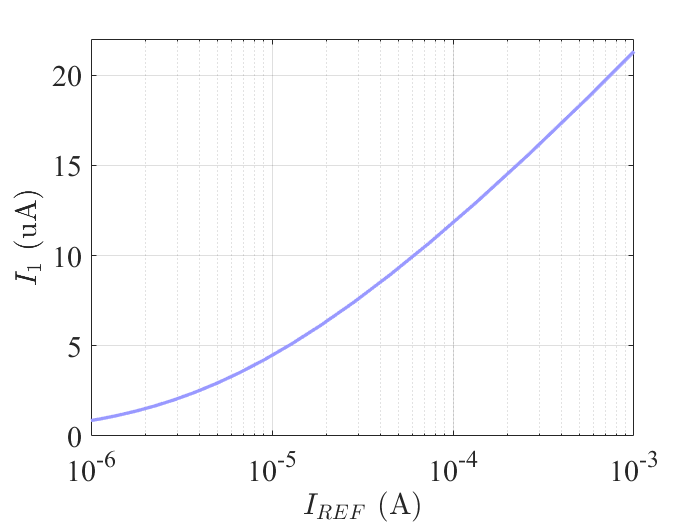

MyExport_pdf

## 20250425 LCE-04 场效应管

## 20250424  依据 2N7000 测量数据给出 3D 数据处理代码

data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), 3D, current level high (0~125mA), data num1 (Id, Vds, Vgs).txt");
MyDataProcessor_MOS_3D_Data1_IdVdsVgs(data, 'mA', 10);
%MyExport_pdf_modal

data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), 3D, current level high (0~125mA), data num2 (Id, Vgs, Vds).txt");
MyDataProcessor_MOS_3D_Data2_IdVgsVds(data, 'mA');
%MyExport_pdf_modal
%max(data(:, 2))

## 20250423 依据 2N7000 测量数据给出数据处理代码

stc
fieldnames(stc)

X = 1.0e-04 *[
    0.0841
    0.0902
    0.1012
    0.1286
    0.1553
    0.2090
    0.2898
    0.3817
    0.5140
    0.6930
    0.9029];
Y = [0.0001
    0.0001
    0.0001
    0.0002
    0.0004
    0.0006
    0.0009
    0.0014
    0.0022
    0.0032
    0.0045];
MyFit_proportional(X', Y', 1)


data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level mid (0~25mA), data num1 (Id, Vds, Vgs).txt");
data_window = 10;
name = '2N7000';
rO_fit = 1;
rO_window = 10;
R_Ib = 1;
unit_Ic = 'mA';
unit_Ib = 'mA';
%MyDataProcessor_MOS_Data1_IdVdsVgs(data, data_window, name, rO_fit, rO_window, unit_Ic)

data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level mid (0~25mA), data num2 (Id, Vgs, Vds) (2).txt");
data = (data(1:501, :) + data(502:1002, :) + data(1003:1503, :))/3;
data_window = 10;
name = '2N7000';
gm_fit = 1;
gm_window = 10;
unit_Id = 'mA';
%MyDataProcessor_BJT_Data23_IcVbeVce_IbVbeVce_gm_rpi_BetaVbeVce
MyDataProcessor_MOS_Data2_IdVgsVds_gmVgsVds_gmIdVds(data, data_window, name, gm_fit, gm_window, unit_Id);

## 全部汇总


clc, clear, close all
if 1    % 5mA
stc.data1_Id_Vds_Vgs = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level low (0~5mA), data num1 (Id, Vds, Vgs).txt");
data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level low (0~5mA), data num2 (Id, Vgs, Vds).txt");
end
if 1    % 25mA
stc.data1_Id_Vds_Vgs = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level mid (0~25mA), data num1 (Id, Vds, Vgs).txt");
data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level mid (0~25mA), data num2 (Id, Vgs, Vds) (2).txt");
end
if 0    % 125mA
stc.data1_Id_Vds_Vgs = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level high (0~125mA), data num1 (Id, Vds, Vgs).txt");
data = readmatrix("D:\aa_MyExperimentData\Raw data backup\[Experiment] 20250423_2129 NMOS 2N7000 (onsemi, KH32), current level high (0~125mA), data num2 (Id, Vgs, Vds).txt");
end

data = (data(1:501, :) + data(502:1002, :) + data(1003:1503, :))/3;
stc.data2_Id_Vgs_Vds = data;

stc.name = '2N7000';
stc.data_window = 10;
stc.rO_fit = 1;
stc.rO_window = 10;
stc.unit_Id = 'mA';
stc.gm_fit = 1;
stc.gm_window = 10;
stc.Ron_max = 20;
stc.gmId_max = 11;

stc_fig = MyDataProcessor_MOS_2D_AllData(stc);
%MyDataProcessor_MOS_2D_AllData_figExport(stc_fig)
stc_fig.stc_Id_Vgs_Vds.axes.YScale = 'log';

stc_fig.stc_gm_Id_Vds.fit_power
X_Id = stc_fig.stc_Id_Vgs_Vds.Y1(1:end-1)
Y_gm = stc_fig.stc_Id_Vgs_Vds.Y2.*X_Id
%MyExport_pdf

fit = stc_fig.stc_gm_Id_Vds.fit_power
V_A = 50;
%Id = Id_array
A1 = @(Id) V_A/2*(fit(Id/2)'./(Id/2));
A2 = @(Id) V_A*fit(Id)'./Id;
A_v = @(Id) V_A/2*(fit(Id/2)'./(Id/2)) .* (V_A*fit(Id)'./Id)
Id_array = linspace(0.1e-3, 25e-3, 200)
stc = MyPlot(Id_array, 20*log(A_v(Id_array))/log(10))
stc.axes.YLim(2) = 100;
MyPlot(Id_array, A1(Id_array))
MyPlot(Id_array, A2(Id_array))
%yline(10^(90/20))
%yline(10^(80/20))

## 20250418 LCE-03 功率放大器

clc, clear, close all
% 导出波形数据分析失真度
%stc = MyOscilloscope_MSO2202A_Read_OneCh(2)
stc = MyOscilloscope_MSO2202A_read_alldata(2, 3);
stc.stc_spectrum.ax1.XLim = [0 100e3];

stc.stc_spectrum.ax1.YScale = 'log';
stc.stc_spectrum.ax1.YLim = [1e-4 10^1];
stc.stc_spectrum.ax1.YTick = logspace(-4, 1, 6);
%MyExport_pdf_docked

%save('LCE-03 (20250418) 功率放大器输出数据 (input 370mVpp 3kHz, Load 3R75 Ohm).mat', 'stc')
%save('LCE-03 (20250418) 功率放大器输出数据 (input 370mVpp 3kHz, Load 3R75 Ohm).txt', 'data', '-ascii')

load("LCE-03 (20250418) 功率放大器输出数据 (input 370mVpp 3kHz, Load 3R75 Ohm).mat");

amp = stc.stc_spectrum.P1;
f = stc.stc_spectrum.f;
step = 3000;
f_max_array = [1e5, 1e6, 1e7, f(end)];
distor_total_array = zeros(size(f_max_array));

for k = 1:length(f_max_array)
    f_max = f_max_array(k);
    f_array = 3e3:3e3:f_max;
    len = length(f_array);
    
    amp_array = zeros(size(f_array));
    search = 3; % 共 search*2 + 1 个点
    for i = 1:len
        tv = find(f > f_array(i), 1);
        [~, ind] = max( amp((tv-search):(tv+search)) );
        tv = tv - search - 1 + ind;
        amp_array(i) = amp(tv);
    end
    
    % 计算各谐波失真和总谐波失真
    distor = amp_array./amp_array(1) * 100;  % unit: %
    distor_total = norm(distor(2:end));
    distor_total_array(k) = distor_total;
    %disp(['f_max = ', num2str(f_max)])
end

f_array
distor_total_array  % 总谐波失真结果


% 作出谐波失真图
stc2 = MyScatter(f_array, distor);
stc2.axes.YScale = 'log';
%stc2.axes.XScale = 'log';
stc2.axes.YLim = [0 1];
%sizedata = distor./distor(1) * 400;
%sizedata(sizedata < 100) = 100;
sizedata = zeros(size(distor)) + 100;
sizedata(1:10) = 400;

stc2.scatter.scatter_1.SizeData = 200;
MyFigure_ChangeSize_2048x512;
stc2.label.x.String = 'Freuqency $f$ (Hz)';
stc2.label.y.String = 'Percent of Harmonic Distortion';
stc2.axes.YTickLabel =  [{'0.01 %'}
                            {'0.1 %'}
                            {'1 %' }];
stc2.leg.Visible = 'off';
stc2.axes.XLim = [0 5e7] ;
%MyExport_pdf
stc2.axes.XScale = 'log';
stc2.axes.XLim = [1000 5e7] 
%MyExport_pdf

% 30 Ohm 效率
R_L = 30
V_out_pp = 27.9
V1 = 14.995 
I1 = 0.158
V2 = 14.999
I2 = 0.154


VCC = 15
P1 = V1*I1
P2 = V2*I2
V_out_amp = V_out_pp/2
P_out_av = V_out_amp^2/(2*R_L)
P_DC_av = V1*I1 + V2*I2
eta_1 = P_out_av/P_DC_av
eta_2 = pi*V_out_amp/(4*VCC)

% 3.75 Ohm 效率
R_L = 3.75
V_out_pp = 24.7
V1 = 14.994
I1 = 1.043
V2 = 14.999
I2 = 1.047


VCC = 15
P1 = V1*I1
P2 = V2*I2
V_out_amp = V_out_pp/2
P_out_av = V_out_amp^2/(2*R_L)
P_DC_av = V1*I1 + V2*I2
eta_1 = P_out_av/P_DC_av
eta_2 = pi*V_out_amp/(4*VCC)

## 20250415

C = 220e-6;
f = [1 10 100];
Z = 1./(2*pi*f*C)


R_1 = 22e3;
R_2 = 22e3;
R_3 = 680;
C_1 = 22e-6;
C_2 = 22e-6;
f = logspace(0, 6, 500);
s = 1j*2*pi*f;
Z_C1 = 1./(s*C_1);
Z_C2 = 1./(s*C_2);
A_v = R_1./(R_1 + Z_C1) .* ( 1 + R_2./(R_3 + Z_C2) );
stc = MyPlot(f, A_v);
stc.axes.XScale = 'log';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y.String = 'Closed-Loop Gain $A_v$';
ylim([0 35])
%MyFigure_ChangeSize_2048x512

## 20250415 Op Amp 测试中的问题探究 (AC Gain 低频异常降低)

% Possible Cause 1: RC 低通网络导致输入衰减
data_1nF = readmatrix("D:\aa_MyExperimentData\Raw data backup\Op Amp Meas of NE5532P (20250414), AC Gain (unit dB), input 1nF + 1MOhm.txt");
data_1uF = readmatrix("D:\aa_MyExperimentData\Raw data backup\Op Amp Meas of NE5532P (20250414), AC Gain (unit dB), input 1uF + 1MOhm.txt");
data_10uF_pos = readmatrix("D:\aa_MyExperimentData\Raw data backup\Op Amp Meas of NE5532P (20250414), AC Gain (unit dB), input 220uF (正极指向开关) + 1MOhm.txt");
data_10uF_neg = readmatrix("D:\aa_MyExperimentData\Raw data backup\Op Amp Meas of NE5532P (20250414), AC Gain (unit dB), input 220uF (负极指向开关) + 1MOhm.txt");

gain = [data_1nF(:, 2), data_1uF(:, 2), data_10uF_pos(:, 2), data_10uF_neg(:, 2)]';
f = data_1nF(:, 1)';
stc = MyPlot(f, gain);
stc.axes.XScale = 'log';
stc.leg.String = ["C = 1 nF"; "C = 1 uF"; "C = 220 uF (+)"; "C = 220 uF (-)";]

## 20250413 Op Amp 测试 (NE5532)

R6 = 3.9e3;
R66 = 390e3;
R7 = 3.9e3;
R77 = 390e3;

TP1 = [
498.55e-3   % V_IO
-353.1e-3   % I_B, SW1, R7
1.3594   % I_B, SW2, R6
];

V_OS = TP1(1)/1001
I_B_neg = -(TP1(2) - TP1(1))/(1001*R7)
I_B_pos = (TP1(3) - TP1(1))/(1001*R6)
I_B = 0.5*(I_B_pos + I_B_neg)
I_OS = (I_B_pos - I_B_neg)

% DC Gain
Delta_TP1 = 496.45e-3 - TP1(1);
Delta_TP2 = -3.6784 - 521.2e-3;
A_OL = 1001*Delta_TP2/Delta_TP1
A_OL_dB = 20*log(A_OL)/log(10)

% DC CMRR
Delta_VCM = 8;
Delta_TP1 = 495.15e-3 - TP1(1);
CMRR = 1001*Delta_VCM/Delta_TP1
CMRR_dB = 20*log(abs(CMRR))/log(10)

% DC PSRR
Delta_TP1 = 477.05e-3 - TP1(1);
Delta_VPS_total = 10 - 24;
PSRR_dc = 1001*Delta_VPS_total/Delta_TP1
PSRR_dB = 20*log(abs(PSRR_dc))/log(10)

% AC Gain
C = 1e-9;
f = 200;
omega = 2*pi*f;
Z_C = 1/(omega*C)
(1 + (Z_C + 1e6)/1e2)* 10 / 4

## 20250410 EET 推导 CS

% Z_in_0
syms V_out V_pi C_L s R_L r_pi g_m C_pi s V_in R_S C_mu C_GS C_GD C_DB C_SB
syms V_x I_x 
re_V_out = (-I_x - g_m*V_x) / (g_m + s*C_DB + 1/R_L)
eq1 = (-V_x)*(1/R_S + s*C_GS) + I_x == V_out*(s*C_GS + 1/R_S);
eq1 = subs(eq1, V_out, re_V_out);
V_x = solve(eq1, V_x);
Z_in_0 = simplifyFraction(V_x/I_x);
Z_out_0 = -1/g_m;

% 求 H(s)
H_0 = -(g_m*R_L)/(1+s*R_L*C_DB) * 1/(1+s*R_S*C_GS);
Z = 1/(s*C_GD);
H = H_0 * (1 + Z_out_0/Z) / (1 + Z_in_0/Z);
H = simplifyFraction(H);
[numerator, denominator] = numden(H); % 提取分子和分母
% 提取 zero 和 denominator 的 As^2 + Bs + C
zero = solve(numerator) % 求出 zero
C = subs(denominator, s, 0)
B = subs(expand( (denominator - C)/s ), s, 0)
A = subs(expand( denominator/s^2 ), s, inf)

% 20250412 验证 Z_d = A_Z_inf/A_Z_0 * Z_n

A_Z_inf = 1/(1 + s*R_S*C_GS) * (-g_m*R_L)/(1 + s*R_L*C_DB)

## 20250409 频响公式推导

% CC (EF)
clc, clear
syms V_out V_pi C_L s R_L r_pi g_m C_pi s V_in R_S C_mu C_GS C_GD C_DB C_SB
% 提取 Razavi 的结果
re_V_pi = V_out*C_L*s / (1/r_pi+g_m+C_pi*s)    
eq = (V_out + V_pi - V_in)/R_S +(V_out + V_pi)*C_mu*s + V_pi/r_pi + V_pi*C_pi*s == 0
% 将 R_L 考虑j进去
re_V_pi = subs(re_V_pi, C_L*s, C_L*s + 1/R_L)     
eq = subs(eq, C_L*s, C_L*s + 1/R_L)     
eq = simplify(subs(eq, V_pi, re_V_pi))
A_v = simplifyFraction(solve(eq, V_out))/V_in
[numerator, denominator] = numden(A_v) % 提取分子和分母
numerator = (numerator/R_L) % 分子分母同除以 R_L
denominator = expand(denominator/R_L) % 分子分母同除以 R_L

% 提取 As^2 + Bs + C
zero = solve(numerator) % 求出 zero
C = subs(denominator, s, 0)
B = subs(expand( (denominator - C)/s ), s, 0)
A = subs(expand( denominator/s^2 ), s, inf)

BJT = subs([A; B; C], R_L, inf)
BJT_no_Rl = subs(expand(BJT/BJT(3)), R_L, inf);
BJT_no_Rl = subs(BJT_no_Rl, g_m*r_pi + 1, g_m*r_pi) % 继续作近似 (gm rpi + 1) = g_m r_pi

% 由 BJT 得到 MOS, 只需 r_pi to inf, C_pi to C_GS, C_mu to C_GD, C_L to (C_L+C_SB)
MOS = subs(expand([A; B; C]/r_pi), r_pi, inf);   
MOS = subs(MOS, C_pi, C_GS);
MOS = subs(MOS, C_mu, C_GD);
MOS = subs(MOS, C_L, C_L + C_SB);
MOS

MOS_no_Rl = subs(MOS, R_L, inf)

a = 2.58e-21;
b = 5.8e-11;
eq = @(s) a*s^2 + b*s + 1
omega = solve(eq, s)
f = round(abs(omega)/(2*pi),0)


syms x;
f = (x^2 + 1) / (x^2 - 1) % 定义一个分式


## 20250407 线电作业

% 3.4.9
% 晶体管参数
phi = 0.7;  % 2 \Phi
gamma = 0.4;
V_TH0 = 1;
K_p = 20e-6;
W_d_L = 30;
eta = 0.1;  % gmb = eta*gm
lambda = 0.01; V_A = 1/lambda;


% 电路参数
V_DD = 5;
V_G = V_DD - 2;
R_S = 1e3;
R_D = 0;

% 求解 I_D (考虑 body 和 modulation)
func_wihout_second_effcets = @(I_D) I_D - ...
    0.5*K_p*W_d_L  *  (  V_G - I_D*R_S - V_TH0  )^2;
I_D = fzero(func_wihout_second_effcets, [0 2e-3])
I_D*1000
V_GS = V_G - I_D*R_S
V_DS = V_DD - I_D*(R_D+R_S)
V_OV = V_GS - V_TH0

% 求解 I_D (考虑 body 和 modulation)
func = @(I_D) I_D - ...
    0.5*K_p*W_d_L  *  (  V_G - I_D*R_S - V_TH0 - gamma*( sqrt(phi + I_D*R_S) - sqrt(phi) )  )^2 ...
    * (  1 + lambda*( V_DD - I_D*(R_D+R_S) )  );
I_D = fzero(func, [0 2e-3])
I_D*1000
V_GS = V_G - I_D*R_S
V_DS = V_DD - I_D*(R_D+R_S)
V_TH = V_TH0 + gamma*( sqrt(phi + I_D*R_S) - sqrt(phi) )
V_OV = V_GS - V_TH
I_D == 0.5*K_p*W_d_L*V_OV^2*(1+lambda*V_DS)

% step 0: small-signal quantities
g_m = sqrt(2*K_p*W_d_L*I_D)
g_m*1000
g_mb = eta*g_m
r_O = (V_A + V_DS)/I_D
r_O/1000

% step 1: R_in
R_in = inf

% step 2: R_out
R_S0 = MyParallel_n([1/g_m, 1/g_mb, r_O])
R_out = MyParallel(R_S, R_S0)

% step 3: A_v
G_m = -g_m/(1+R_D/r_O)
A_v = -G_m*R_out

% 3.4.8 
% 晶体管参数
phi = 0.7;  % 2 \Phi
gamma = 0.4;
V_TH0 = 1.75;
K_p = 40e-6;
W_d_L = 20;
eta = 0.1;  % gmb = eta*gm
lambda = 0.01; V_A = 1/lambda;


% 电路参数
V_DD = 10;
V_G = 3/8*V_DD;
R_S = 0.5e3;
R_D = 5e3;

% 求解 I_D (考虑 body 和 modulation)
func_wihout_second_effcets = @(I_D) I_D - ...
    0.5*K_p*W_d_L  *  (  V_G - I_D*R_S - V_TH0  )^2;
I_D = fzero(func_wihout_second_effcets, [0 2e-3])
I_D*1000
V_GS = V_G - I_D*R_S
V_DS = V_DD - I_D*(R_D+R_S)

% 求解 I_D (考虑 body 和 modulation)
func = @(I_D) I_D - ...
    0.5*K_p*W_d_L  *  (  V_G - I_D*R_S - V_TH0 - gamma*( sqrt(phi + I_D*R_S) - sqrt(phi) )  )^2 ...
    * (  1 + lambda*( V_DD - I_D*(R_D+R_S) )  );
I_D = fzero(func, [0 2e-3])
I_D*1000
V_GS = V_G - I_D*R_S
V_DS = V_DD - I_D*(R_D+R_S)

% step 0: small-signal quantities
g_m = sqrt(2*K_p*W_d_L*I_D)
g_m*1000
g_mb = eta*g_m
r_O = (V_A + V_DS)/I_D
r_O/1000

% step 1: R_in
R_S0 = MyParallel_n([1/g_m, 1/g_mb, r_O])
R_in = R_S + (1+R_D/r_O)*R_S0

% step 2: R_out
R_coll = (1 + R_S/R_S0)*r_O
R_out = MyParallel(R_D, R_coll)

% step 3: A_v
G_m = -1/(R_S + R_S0)
A_v = -G_m*R_out

## 20250329 (线电期中实验：CE Amp)

[0.1592, 4.4175] -  2.7459 
[-2.5867, 1.6716]/15*1000

% dc point calculation
clc, clear, close all

% 电路参数
R_1 = 24e3;
R_2 = 10e3;
R_C1 = 1e3;
R_E1 = 51;
R_E2 = 300;

% SPICE 参数
Vcc = 5;
I_S = 4.679e-14;
R_B0 = 1;
R_C0 = 1;
R_E0 = 0.2598;
beta = 458.7;
n_f = 1.01;
V_A = 52.64;

% 其它参数
R_E_all = R_E0 + R_E1 + R_E2
R_all = R_C0 + R_C1 + R_E0 + R_E1 + R_E2
V_T = 26e-3;


tv_Ic = Vcc/R_all*1000
tv_Ib = tv_Ic/beta*1000

func_I_C = @(V_BE, V_CE) I_S*exp(V_BE/(n_f*V_T)).*(1 + V_CE/V_A)
array_V_BE = linspace(600, 670, 8)*10^(-3);
array_V_CE = linspace(1, 5, 100);
matrix_I_C = func_I_C(array_V_BE, array_V_CE');

MyPlot(array_V_CE, matrix_I_C');

V_B = @(I_C) (Vcc - I_C*R_1/beta) / (1 + R_1/R_2)
eq = @(I_C) I_C - I_S .* exp(  (V_B(I_C) - I_C.*R_E_all) / (n_f*V_T)  ) .* (1 + (Vcc - I_C.*R_all)/V_A)
range_I_C = linspace(0, 5e-3, 200);
stc = MyPlot_2window(range_I_C, eq(range_I_C), range_I_C, abs(eq(range_I_C)));
stc.ax1.YLim = [-1 1]; 
stc.ax1.XLim = [0 range_I_C(end)];
stc.ax2.YLim = [-1 1]; 
stc.ax2.XLim = [0 range_I_C(end)];
stc.ax2.YScale = 'log';

I_C = fzero(eq, [0 4e-3]);
disp(['I_C = ', num2str(I_C*1000, '%.8f') ' mA'])  

I_B = I_C/beta
V_B_ = V_B(I_C)
V_C = Vcc - I_C*(R_C0 + R_C1)
V_E = I_C*R_E_all
V_BE = V_B(I_C) - V_E
V_CE = V_C - V_E


% dc point simulation
V_C = 2.74563
V_B = 1.43601
V_E = 0.793003
V_CE = V_C - V_E
V_BE = V_B - V_E

% ac gain calculation
f = 1e3;
omega = 2*pi*f;
C_in = 10e-6;
C_out = 10e-6;
C_E = 100e-6;

R_B = R_B0 + MyParallel_n([1/(1j*omega*C_in), R_1, R_2])
R_C = R_C1
R_E = R_E1 + MyParallel(R_E2, 1/(1j*omega*C_E))

r_O = V_A/I_C
g_m = I_C/(n_f*V_T)
r_pi = beta/g_m

R_coll = r_O * (  1 + (beta/(r_pi + R_B) + 1/r_O)*MyParallel(R_E, r_pi) )
R_out = MyParallel(R_C, R_coll)
G_m = beta/(r_pi + R_B) / R_E * MyParallel_n([R_E, (r_pi + R_B)/(beta + 1), r_O])
A_v = -G_m*R_out
A_v_abs = abs(A_v)

% ac gain frequency response
f = logspace(0, 6, 7*100);
omega = 2*pi*f;
C_in = 10e-6;
C_out = 10e-6;
C_E = 100e-6;

R_B = R_B0 + MyParallel_n([1./(1j*omega*C_in), R_1, R_2]);
R_C = R_C1;
R_E = R_E1 + MyParallel(R_E2, 1./(1j*omega*C_E));

r_O = V_A/I_C;
g_m = I_C/(n_f*V_T);
r_pi = beta/g_m;

R_coll = r_O * (  1 + (beta./(r_pi + R_B) + 1/r_O) .* MyParallel(R_E, r_pi) );
R_out = MyParallel(R_C, R_coll);
%G_m = beta./(r_pi + R_B) ./ R_E .* MyParallel_n([R_E, (r_pi + R_B)./(beta + 1), r_O])
tv_1 = zeros(size(R_E)) +  (r_pi + R_B)./(beta + 1);
tv_2 = zeros(size(R_E)) +  r_O;
G_m = beta./(r_pi + R_B) ./ R_E .* MyParallel_n([R_E', tv_1', tv_2']);
A_1 = -G_m.*R_out;  % 注意这里还不是实际的小信号增益, 因为没有考虑输入电阻
A_v = A_1 .* (1j*omega*C_in) .* MyParallel_n([zeros(size(omega')) + R_1, zeros(size(omega')) + R_2, 1./(1j*omega'*C_in)])
A_v_abs = abs(A_v);
A_v_dB = 20*log(A_v_abs)/log(10);
abs(A_v(1));
phase = rad2deg(angle(A_v));
%phase(phase > 90) = phase(phase > 90) - 360;

%stc = MyYYPlot([f; f], [A_v_abs; phase]);
stc.axes.XScale = 'log';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Gain $A_v$ (V/V)';
stc.label.y_right.String = 'Phase $\theta$ ($^\circ$)';
stc.leg.Visible = 'off';

%stc = MyYYPlot([f; f], [A_v_dB; phase]);
stc.axes.XScale = 'log';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Gain $A_v$ (dB)';
stc.label.y_right.String = 'Phase $\theta$ ($^\circ$)';
stc.leg.Visible = 'off';

% Output Impedance
f = logspace(0, 6, 7*100);
omega = 2*pi*f;
C_in = 10e-6;
C_out = 10e-6;
C_E = 100e-6;

R_B = R_B0 + MyParallel_n([1./(1j*omega*C_in), R_1, R_2]);
R_C = R_C1;
R_E = R_E1 + MyParallel(R_E2, 1./(1j*omega*C_E));

r_O = V_A/I_C;
g_m = I_C/(n_f*V_T);
r_pi = beta/g_m;

R_coll = r_O * (  1 + (beta./(r_pi + R_B) + 1/r_O) .* MyParallel(R_E, r_pi) );
R_out = MyParallel(R_C, R_coll);
R_out_abs = abs(R_out);
%G_m = beta./(r_pi + R_B) ./ R_E .* MyParallel_n([R_E, (r_pi + R_B)./(beta + 1), r_O])
tv_1 = zeros(size(R_E)) +  (r_pi + R_B)./(beta + 1);
tv_2 = zeros(size(R_E)) +  r_O;
G_m = beta./(r_pi + R_B) ./ R_E .* MyParallel_n([R_E', tv_1', tv_2']);
A_1 = -G_m.*R_out;  % 注意这里还不是实际的小信号增益, 因为没有考虑输入电阻
A_v = A_1 .* (1j*omega*C_in) .* MyParallel_n([zeros(size(omega')) + R_1, zeros(size(omega')) + R_2, 1./(1j*omega'*C_in)])
A_v_abs = abs(A_v);
A_v_dB = 20*log(A_v_abs)/log(10);
abs(A_v(1));
phase = rad2deg(angle(A_v));
%phase(phase > 90) = phase(phase > 90) - 360;

stc = MyYYPlot([f; f], [A_v_abs; R_out_abs]);
stc.axes.XScale = 'log';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Gain $A_v$ (V/V)';
stc.label.y_right.String = 'Output Impedance $|Z_{out}|$ ($\Omega$)';
stc.leg.Visible = 'off';

% input/output voltage range calculation
if 0
    eq = @(x) x*(R_C0 + R_C1 + R_E0 + R_E1) + n_f*V_T*log(x/I_S) - Vcc + I_C*R_E2 - 0.8
    I_C_max = fzero(eq, [1e-6 5e-3])
    %I_C_max = ( Vcc - I_C*R_E2 - V_BE ) / (R_C0 + R_C1 + R_E0 + R_E1)
    
    V_C_min = Vcc - I_C_max*1e3
    V_B_max = n_f*V_T * log(I_C/I_S) + I_C*R_E2 + I_C_max*(R_E0 + R_E1)
    (V_B_max - V_B)*1000
    %V_BE_max = log(I_C_max/I_S) * n_f*V_T
end

% v_in_max, saturation
I_C_max = (Vcc - I_C*R_E2 - 0.15) / (R_C0 + R_C1 + R_E0 + R_E1)
V_C_min = Vcc - I_C_max*(R_C0 + R_C1)
v_out_min = V_C_min - V_C
v_in_max = v_out_min/(-16)

% v_in_min, threshold
I_C_min = 0.5e-3
V_C_max = Vcc - I_C_min*(R_C0 + R_C1)
v_out_max = V_C_max - V_C
v_in_min = v_out_max/(-15.7*0.75)


% Large-Signal Gain (f = 10 KHz)
I_C = linspace(0, 4e-3, 100);

f = 10e3;
omega = 2*pi*f;
C_in = 10e-6;
C_out = 10e-6;
C_E = 100e-6;

R_B = R_B0 + MyParallel_n([1./(1j*omega*C_in), R_1, R_2]);
R_C = R_C1;
R_E = R_E1 + MyParallel(R_E2, 1./(1j*omega*C_E));

r_O = V_A./I_C;
g_m = I_C/(n_f*V_T);
r_pi = beta./g_m;

R_coll = r_O .* (  1 + (beta./(r_pi + R_B) + 1./r_O) .* MyParallel(R_E, r_pi) );
R_out = MyParallel(R_C, R_coll);
%G_m = beta./(r_pi + R_B) ./ R_E .* MyParallel_n([R_E, (r_pi + R_B)./(beta + 1), r_O])
tv_1 = (r_pi + R_B)./(beta + 1);
tv_2 = r_O;
tv_R_E = zeros(size(I_C)) + R_E;
G_m = beta./(r_pi + R_B) ./ R_E .* MyParallel_n([tv_R_E', tv_1', tv_2']);
A_1 = -G_m.*R_out;  % 注意这里还不是实际的小信号增益, 因为没有考虑输入电阻
A_v = A_1 .* (1j*omega*C_in) .* MyParallel_n([zeros(size(omega')) + R_1, zeros(size(omega')) + R_2, 1./(1j*omega'*C_in)]);
A_v_abs = abs(A_v);
A_v_dB = 20*log(A_v_abs)/log(10);
abs(A_v(1));
phase = rad2deg(angle(A_v));
%phase(phase > 90) = phase(phase > 90) - 360;

stc = MyYYPlot([I_C; I_C]*10^3, [A_v_abs; A_v_dB]);
stc.label.x.String = 'Collector Current $I_C$ (mA)';
stc.label.y_left.String = 'Gain $A_v$ (V/V)';
stc.label.y_right.String = 'Gain $A_v$ (dB)';
stc.leg.Visible = 'off';
stc.axes.YLim = [0 20];
yyaxis('right')
stc.axes.YLim = [0 30];

## 20250328

A_dB_theo = 44.8689
A_dB_simu = 44.7787
A_theo = 10^(A_dB_theo/20)
A_simu= 10^(A_dB_simu/20)
MyGet_eta(A_theo, A_simu)

V = (10 + 3e-3) - (2 - 1e-3)
R = 1e3 - 10
I = V/R*1000 - 8

V = (10 - 3e-3) - (2 + 1e-3)
R = 1e3 + 10
I = V/R*1000 - 8

## 20250327

A = [4 2 1 3 5]
[A_sort, Index] = sort(A, 'descend')

clc, clear
f = 1e3;
omega = 2*pi*f;
func = @(t) 2 + sin(omega*t) + 0.6*sin(2*omega*t) + 0.36*sin(3*omega*t) + 0.2*0.3*sin(4*omega*t) + 0.1*exp(t*210);
t = linspace(0, 10 * 1/f, 2^10);
disp(['F_s = ', num2str(1./(t(2) - t(1)))])
stc = MyAnalysis_Spectrum(func(t), t, 0)


clc, clear, close all
Fs = 500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 2000;             % Length of the sampling data


disp(['频谱分辨率: ', num2str(Fs/(L - mod(L, 2)))])

t = (0:L-1)*T;        % Time vector
S = 3 + 0.7*sin(2*pi*50*t) + sin(2*pi*200*t);
S = S + 2*randn(size(t)).*sin(2*pi*200*t);
figure
plot(1000*t, S)
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
Y = fft(S);
P2 = abs(Y/L);  % the two-sided spectrum
midpoint = (L + mod(L, 2))/2;
P1 = P2(1:midpoint+1);   % single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1);

f = (Fs + mod(L, 2)*Fs/L) * (0:midpoint) / L;
f_P2 = Fs*(0:L-1)/L;
plot(f,P1)
plot(f_P2, P2)
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

MyAnalysis_Spectrum_3fig(S, t, [0 1/50*5])

## 20250326

A = 913e-3/51e-6
A_dB = 20*log(A)/log(10)

% 线电期中实验：差放仿真，R_out 计算
data = [
     1	5.28967
     2	6.27844
     3	7.26585
     4	8.25175
     5	9.23596
     6	10.2183
     7	11.1985
     8	12.1763
     9	13.1515
    10	14.1238
    11	15.0927
    12	16.058
    13	17.0193
    14	17.976
    15	18.9277
    16	19.8739
    17	20.8138
    18	21.7469
    19	22.6725
    20	23.5897
    21	24.4978
    22	25.3958
    23	26.2827
    24	27.1576
    25	28.0193
    26	28.8668
    27	29.6987
    28	30.514
    29	31.3112
    30	32.0893
    31	32.8468
    32	33.5825
    33	34.2953
    34	34.9839
    35	35.6474
    36	36.2846
    37	36.8949
    38	37.4775
    39	38.0318
    40	38.5576
    41	39.0546
    42	39.5229
    43	39.9627
    44	40.3743
    45	40.7584
    46	41.1156
    47	41.4469
    48	41.7531
    49	42.0355
    50	42.2951
    51	42.5333
    52	42.7512
    53	42.9501
    54	43.1313
    55	43.296
    56	43.4455
    57	43.581
    58	43.7035
    59	43.8142
    60	43.914
    61	44.004
    62	44.0849
    63	44.1578
    64	44.2232
    65	44.2819
    66	44.3346
    67	44.3818
    68	44.4241
    69	44.4619
    70	44.4958
    71	44.5261
    72	44.5532
    73	44.5775
    74	44.5991
    75	44.6185
    76	44.6357
    77	44.6512
    78	44.6649
    79	44.6772
    80	44.6882
    81	44.698
];
A_DM_dB = 44.7787;
A_DM_eq_dB = data(:, 2)';
%A_eq = 10.^(data(:, 2)/20)
R_L = logspace(2, 6, 81);
R_out = R_L .* (10.^( (A_DM_dB - A_DM_eq_dB)/20 )  -  1);

%stc = MyPlot(R_L, R_out);

R_out_theo = zeros(size(R_out)) + 9.2745e3;
A_DM_theo_dB = 44.8689;
A_DM_eq_theo_dB = A_DM_theo_dB - 20*log(1 + R_out_theo./R_L)/log(10);
stc = MyPlot_2window(R_L, R_L, [R_out; R_out_theo], [A_DM_eq_dB; A_DM_eq_theo_dB]);
%stc = MyPlot_2window(R_L, R_L, [R_out; R_out_theo], [(A_DM_eq_dB - A_DM_eq_theo_dB)./A_DM_eq_dB*100]);
stc.ax1.XScale = 'log';
stc.ax2.XScale = 'log';
stc.ax1.YLim = [9250 9350];
stc.ax2.YLim = [0 45];
stc.plot1.leg.String = ["Simulated"; "Theoretical"];
stc.plot2.leg.String = ["Simulated"; "Theoretical"];
stc.plot1.label.x.String = "Load Resistance $R_L$ ($\Omega$)";
stc.plot2.label.x.String = "Load Resistance $R_L$ ($\Omega$)";
stc.plot1.label.y.String = "Output Resistance $R_{out}$ ($\Omega$)";
stc.plot2.label.y.String = "Equivalent DM Gain $A_{DM,eq}$ (dB)";
stc.plot2.leg.Visible = 'on';

R_out = mean(R_out)
MyGet_eta(9.2745e3, R_out)

% 线电作业，单端输入/输出差分放大器
I_EE = 2e-3;
n_f = 0.9925;
V_T = 26e-3;
V_A = 49.77;
beta = 524.9;

R_E = 0.653;
R_C = 6200.78;
R_B = 7.5;

g_m = I_EE/(2*n_f*V_T)
g_m3 = g_m*2
r_pi = beta/g_m
r_O = 2*V_A/I_EE
r_O3 = V_A/I_EE
r_pi3 = beta/g_m3

R_SS = r_O3 + (1 + g_m3*r_O3)*MyParallel(r_O3, r_pi3)


R_in = R_B + r_pi
R_coll = r_O * (  1 + (beta/(r_pi + R_B) + 1/r_O) * MyParallel(R_E, r_pi + R_B)  )
R_out = MyParallel(R_C, R_coll)
G_m = beta / (r_pi + R_B) * (1/R_E) * MyParallel_n([R_E, (r_pi + R_B)/(beta + 1), r_O])
A_DM = - G_m*R_out
A_DM_dB = 20*log(abs(A_DM))/log(10)

A_v = A_DM/2
A_v_dB = 20*log(abs(A_v))/log(10)
R_L = 10e3;
A_v_eq = A_v*R_L/(R_L + R_out)
A_v_eq_dB = 20*log(abs(A_v_eq))/log(10)

## 20250325

I_EE = 2e-3;
n_f = 0.9925;
V_T = 26e-3;
V_A = 49.77;
beta = 524.9;

R_E = 0.653;
R_C = 5100.78;
R_B = 7.5;

g_m = I_EE/(2*n_f*V_T)
r_pi = beta/g_m
r_O = 2*V_A/I_EE

R_coll = r_O * (  1 + (beta/(r_pi + R_B) + 1/r_O) * MyParallel(R_E, r_pi + R_B)  )
R_out = MyParallel(R_C, R_coll)
G_m = beta / (r_pi + R_B) * (1/R_E) * MyParallel_n([R_E, (r_pi + R_B)/(beta + 1), r_O])
A_DM = - G_m*R_out
A_DM_dB = 20*log(abs(A_DM))/log(10)
R_out_DM = 2*R_out

R_L = 10e3;
A_DM_eq = A_DM*R_L/(R_L + R_out_DM)
A_DM_eq_dB = 20*log(abs(A_DM_eq))/log(10)
%A_DM_eq_dB = 20*log(abs(A_DM*R_L/(R_L + R_out)))/log(10)

R_C = 5.1e3;
I_EE = 2e-3;
V_T = 26e-3;

% 求解 Gm
clc, clear, close all
syms i_x g_mN v_in1 v_in2 v_P r_ON r_OP g_mP v_A R_3 R_SS
eq = [
i_x == g_mN*(v_in2 - v_P) - v_P/r_ON + g_mP*v_A
- v_A/R_3 == v_P/R_SS - (i_x - g_mP*v_A)
- v_A/R_3 == (v_A - v_P)/r_ON + g_mN*(v_in1 - v_P)
]

% 求解 v_A 和 v_P
re_v_A = solve(eq(2), v_A)  % 2 求解 v_A
eq(1) = subs(eq(1), v_A, re_v_A);   % 代入 1
re_v_P = solve(eq(1), v_P); % 1 求解 v_P
re_v_A = subs(re_v_A, v_P, re_v_P); % v_P 结果代回 v_A
re_v_P = simplifyFraction(re_v_P)
re_v_A = simplifyFraction(re_v_A)

% v_A 和 v_P 代入 3 求解 i_x
eq(3) = subs(eq(3), v_P, re_v_P);
eq(3) = subs(eq(3), v_A, re_v_A);
i_x = solve(eq(3), i_x);
i_x = simplifyFraction(i_x)
%simplifyFraction(i_x/r_ON/g_mN)  

% 化简 i_x 的表达式
A_1 = simplifyFraction(subs(i_x, v_in2, 0)/v_in1)     % 求 v_in1 的系数 A_1
A_2 = simplifyFraction(subs(i_x, v_in1, 0)/v_in2)     % 求 v_in2 的系数 A_2

syms X Y A B
eq = [
A == X + Y/2
B == -X + Y/2
]
[X, Y] = solve(eq, [X, Y])

% 准备代入 R_3
R_2 = (r_ON + MyParallel(1/g_mP, r_OP)) / (1 + g_mN*r_ON);
re_R_3 = MyParallel(R_SS, R_2 )

% 求解 Gm_DM
G_m_DM = X;
G_m_DM = subs(G_m_DM, A, A_1);  % 代入 A_1
G_m_DM = subs(G_m_DM, B, A_2);  % 代入 A_2
G_m_DM = subs(G_m_DM, R_3, re_R_3);  % 代入 R_3
G_m_DM = simplifyFraction(G_m_DM);
G_m_DM = g_mN*r_ON*simplifyFraction(G_m_DM/(g_mN*r_ON))    % 观察提取公因式后的式子

% 求解 Gm_CM
G_m_CM = Y;
G_m_CM = subs(G_m_CM, A, A_1);  % 代入 A_1
G_m_CM = subs(G_m_CM, B, A_2);  % 代入 A_2
G_m_CM = subs(G_m_CM, R_3, re_R_3);  % 代入 R_3
G_m_CM = simplifyFraction(G_m_CM)

if 0
% 验证 Gm_DM 与 A_DM 中的结果是否相同
R_4 = r_ON + (r_ON + MyParallel(1/g_mP, r_OP)) / (1 + R_2/R_SS);
R_out = MyParallel_n([r_OP, R_4, R_4 * (1+1/(g_mP*r_OP)) * (1+R_2/R_SS)]);   % 已校验
A_DM = (g_mN*r_ON)  ... % 已校验
    /  ( ...
    2*(r_ON + r_OP) / (r_OP*(1+g_mP*MyParallel(1/g_mP, r_OP))) ...
    + ...
    2*g_mP*r_OP / (2*g_mP*r_OP+1)^2 / ( (r_ON+r_OP)/(2*(1+g_mN*r_ON)*R_SS+r_ON)) ...
    )

check_DM = simplify(simplifyFraction(G_m_DM*R_out + A_DM))  % 验证 A_DM
%check_CM = simplify(simplifyFraction(G_m_CM*R_out - A_CM))  % 验证 A_CM

end

% 计算近似条件下的 G_m_DM 和 G_m_CM
G_m_DM = simplifyFraction(limit(G_m_DM, R_SS, inf));
G_m_DM = simplifyFraction(limit(G_m_DM, r_ON, inf));
%G_m_DM = simplifyFraction(limit(G_m_DM, R_SS, inf));
G_m_DM

%G_m_CM = simplifyFraction(limit(G_m_CM, R_SS, inf));
%G_m_CM = simplifyFraction(limit(G_m_CM, r_ON, inf));
%G_m_CM



tv_i_x = limit(i_x, R_SS, inf)   % R_SS \to infty
G_m = simplifyFraction(tv_i_x/(v_in1 - v_in2))
re_R_3 = (r_ON + MyParallel(1/g_mP, r_OP)) / (1 + g_mN*r_ON)
G_m = simplifyFraction(subs(G_m, R_3, re_R_3))
G_m = simplifyFraction(limit(G_m, r_ON, inf))
%G_m = limit(G_m, r_OP, inf)


% ax + by = A(x - y) + B(x + y)/2
syms a b A B
eq = [
a == A + B/2
b == -A + B/2
]
[A, B] = solve(eq, [A B])
re_a = g_mP*R_3*r_ON
re_b = - (R_3 + r_ON)


## 20250324

R_C = 5.6e3;
R_E = 100;
R_B = 200;
beta = 100;
I_C = 1e-3;
V_T = 26e-3;
g_m = I_C/V_T
r_pi = beta*V_T/I_C

A_v = - R_C / (R_E + 1/g_m + R_B/(beta + 1))
20e-3*A_v

R_L = 5.6e3;
A_v/3
A_v/3*20e-3

R_in_DM = 2*( r_pi + (beta+1)*R_E )

V_A = 100;
R_4 = 300;

I_REF = (15 - 0.7)/(14e3 + 300)
r_O6 = 100e3;
R_T6 = 300 + MyParallel(26, 100e3)
R_Thev = MyParallel(14e3, R_T6)

r_O5 = 100e3;
R_B = R_Thev;
r_pi = 2.6e3;
R_E = 300;
MyCaculation_BJT_Rcoll(r_O5, 100, r_pi, R_B, R_E)

R_L = 10e3;
r_O = 200e3;
r_pi = 5.6e3;
R_B = MyParallel(200e3, 1e3 + MyParallel(52, 200e3))
R_coll_4 = MyCaculation_BJT_Rcoll(200e3, 100, r_pi, R_B, 1e3)
R_out = MyParallel(200e3, R_coll_4)
A_DM = R_out/52
20*log(A_DM)/log(10)
A_DM_eq = R_L/(R_L + R_out)*A_DM
20*log(A_DM_eq)/log(10)

## 20250324

clc, clear
syms v_1 v_2 i_1 i_2 R_D g_mN r_ON r_OP v_P R_SS
eq = [
-i_1*R_D - (i_1 - g_mN*v_1)*r_ON == v_P
-i_2*R_D - (i_2 - g_mN*v_2)*r_ON == v_P
i_1 + i_2 == v_P/R_SS
v_P * ( 2 + (R_D + r_ON)/R_SS ) == g_mN*r_ON*(v_1 + v_2)
]

re_v_P = solve(eq(4), v_P)
eq(1) = subs(eq(1), v_P, re_v_P);
eq(2) = subs(eq(2), v_P, re_v_P)
[i_1, i_2] = solve([eq(1), eq(2)], [i_1, i_2])
simplifyFraction([i_1, i_2])

v_Thev_DM = -R_D*(i_1 - i_2)
v_Thev_DM = simplifyFraction(v_Thev_DM)

v_Thev_CM = -R_D/2*(i_1 + i_2)
v_Thev_CM = simplifyFraction(v_Thev_CM)

simplify(eq(1) + eq(2))

clc, clear
syms v_out i_3 i_4 r_O3 r_O4 g_m4 g_m3 R_Thev v_Thev_DM v_Thev_CM g_mP r_OP r_ON
eq = [
v_out == (i_3 + i_4)*r_O4
i_4 == g_m4*i_3*MyParallel(r_O3, 1/g_m3)
-i_3*MyParallel(r_O3, 1/g_m3) - i_3*R_Thev - v_Thev_DM == v_out
]

re_i_4 = solve(eq(2), i_4);
re_i_3 = solve(eq(3), i_3);
eq(1) = subs(eq(1), i_4, re_i_4);
eq(1) = subs(eq(1), i_3, re_i_3);
re_v_out = solve(eq(1), v_out)


syms v_out i_3 i_4 r_O3 r_O4 g_m4 g_m3 R_Thev v_Thev_DM v_Thev_CM g_mP r_OP r_ON
eq_Razavi = (v_out + v_Thev_DM) * (g_m4*MyParallel(r_O3, 1/g_m3) + 1) / (MyParallel(r_O3, 1/g_m3) + R_Thev) + v_out/r_O4 == 0
re_v_out_Razavi = solve(eq_Razavi, v_out);

simplify(re_v_out_Razavi - re_v_out)    % 验证与 Razavi 的结果是否相同

if 1
    re_v_out = subs(re_v_out, R_Thev, 2*r_ON);
    re_v_out = subs(re_v_out, r_O3, r_OP);     % r_O3 = r_O4 = r_OP
    re_v_out = subs(re_v_out, r_O4, r_OP); 
    re_v_out = subs(re_v_out, g_m3, g_mP);     % g_m3 = g_m4 = g_mP
    re_v_out = subs(re_v_out, g_m4, g_mP);    
    %re_v_out = subs(re_v_out, r_O3, inf)      % g_m3*r_O3 >> 1
end
re_v_out = simplifyFraction(re_v_out)

eV = 1.60218e-19;   % unit: J
J = 1./1.60218e-19;  % unit: eV
h = 6.62607015e-34; 
nu = (1.6+1.9)*eV/h
c = 3e8;
lambda = c/nu

Vcc = 3.7;
R = (Vcc - 3.3)/20e-3
I = 20e-3;
P = I^2*R

x = 0.1/3.7
R_p = 10e3;
R = R_p * (1./x - 1)
y = 2.5e-3/3.7;
R = R_p*y

a = 4.05/0.768 - 1
a*10e3
R_1 = 43e3;
R_2 = 10e3;
0.768*(1+R_1/R_2)

syms R C alpha omega

%R = 10e3;
%C = 10e-9;

Z = MyParallel(R, R + 1/(1j*omega*C/alpha));
H = Z/(Z + 1/(1j*omega*alpha*C)) * R/(R + 1/(1j*omega*C/alpha));
H = simplifyFraction(H)
H_abs = simplifyFraction(abs(H))

H_1(omega) = subs(H, alpha, 1);
H_2(omega) = subs(H, alpha, 2);
H_5(omega) = subs(H, alpha, 5);

Omega_array = logspace(0, 6, 100);
MyPlot_Bode_twoH_omega_2Y(Omega_array, H_1, H_2)

syms Y_1 Y_2 Y_3 Y_4 R C alpha omega

R = 10e3;
C = 10e-9;

Y_1 = 1/R
Y_2 = (1j*omega*C/alpha)
Y_3 = (1j*omega*C*alpha)
Y_4 = 1/R
H = 1 / ( 1 + Y_3 / (Y_1 + Y_2+  Y_1*Y_2/Y_4 + Y_2*Y_3/Y_4)  )
H(omega) = simplifyFraction(H)

H_1(omega) = subs(H, alpha, 1);
H_2(omega) = subs(H, alpha, 2);
H_5(omega) = subs(H, alpha, 5);
H_10(omega) = subs(H, alpha, 10);

Omega_array = logspace(1, 7, 200);
stc = MyPlot_Bode_fourH_omega_2Y(Omega_array, H_1, H_2, H_5, H_10)
stc.plot1.leg.String = ["$\alpha = 1$"; "$\alpha = 2$"; "$\alpha = 5$"; "$\alpha = 10$"; ]
%MyPlot_Bode_twoH_omega_2Y(Omega_array, H_1, H_2)

syms Y_1 Y_2 Y_3 Y_4 R C alpha omega

R = 10e3;
C = 10e-9;

Y_1 = 1j*omega*C
Y_2 = 1/(R)
Y_3 = 1/(R/alpha)
Y_4 = 1j*omega*C
H = 1 / ( 1 + Y_3 / (Y_1 + Y_2+  Y_1*Y_2/Y_4 + Y_2*Y_3/Y_4)  )
H(omega) = simplifyFraction(H)

H_1(omega) = subs(H, alpha, 1);
H_2(omega) = subs(H, alpha, 2);
H_5(omega) = subs(H, alpha, 5);
H_10(omega) = subs(H, alpha, 10);

Omega_array = logspace(1, 7, 200);
stc = MyPlot_Bode_fourH_omega_2Y(Omega_array, H_1, H_2, H_5, H_10)
stc.plot1.leg.String = ["$\alpha = 1$"; "$\alpha = 2$"; "$\alpha = 5$"; "$\alpha = 10$"; ]

R = 10e3;
C = 10e-9;
1/(2*pi*R*C)

clc, clear, close all
syms V_in V_out V_1 Y_1 Y_2 Y_3 Y_4 Y_5 Y_6 omega C R

R = 10e3;
C = 10e-9;

if 1
    Y_1 = 1j*omega*C;
    Y_2 = 1/R;
    Y_3 = 1j*omega*C;
    Y_4 = 1/R;
    Y_5 = 1/(R);
    Y_6 = 1j*omega*(C);
end


V_1 = (Y_1*Y_6 + Y_2*Y_6)/(Y_1*Y_6 - Y_2*Y_5) * V_in
V_2 = -V_1*Y_5/Y_6

%eq = (V_in - V_1)*Y_1 + (V_out - V_1)*Y_3 == V_1*Y_5
%eq = (V_in - V_2)*Y_2 + (V_out - V_2)*Y_4 == V_2*Y_6
eq = subs(eq, V_in, 1)
V_out = solve(eq, V_out)

H(omega) = V_out
%H(omega) = - (-omega^2 + 40000 *1j* omega + 100000000) / (omega^2 - 100000000)
Omega_array = logspace(1, 7, 200);
%stc = MyPlot_Bode_H_omega_2Y(Omega_array, H)
MyPlot_Bode_oneH_f(Omega_array, H)

clc, clear, close all
syms V_in V_out V_1 V_2 Y_1 Y_2 Y_3 Y_4 Y_5 Y_6 omega C R



if 1
    omega = 1e3;
    R = 10e3;
    C = 10e-9;
    Y_1 = 1j*omega*C;
    Y_2 = 1/R;
    Y_3 = 1j*omega*C;
    Y_4 = 1/R;
    Y_5 = 1/(R/2);
    Y_6 = 1j*omega*(2*C);
end

Y_1 = Y_3
Y_2 = Y_4


eq1 = V_1*Y_5 + V_2*Y_6 == 0
eq2 = (V_out - V_1)*Y_3 + (V_out - V_2)*Y_4 == 0
eq3 = (V_in - V_1)*Y_1 + (V_in - V_2)*Y_2 == 0

stc = solve([eq1, eq2], [V_1 V_2])  % 用 V_out 表示 V_1 和 V_2
eq3 = subs(eq3, V_1, stc.V_1);
eq3 = subs(eq3, V_2, stc.V_2)
eq3 = subs(eq3, V_in, 1);
H = solve(eq3, V_out)
H(omega) = simplifyFraction(H)

Omega_array = logspace(1, 7, 200);
%stc = MyPlot_Bode_H_omega_2Y(Omega_array, H)
MyPlot_Bode_oneH_f(Omega_array, H)

clc, clear, close all
syms V_in V_out V_1 V_2 Y_1 Y_2 Y_3 Y_4 Y_5 Y_6 omega C R



if 0
    omega = 1e3;
    R = 10e3;
    C = 10e-9;
    Y_1 = 1j*omega*C;
    Y_2 = 1/R;
    Y_3 = 1j*omega*C;
    Y_4 = 1/R;
    Y_5 = 1/(R/2);
    Y_6 = 1j*omega*(2*C);
end

Y_1 = Y_3
Y_2 = Y_4


eq1 = V_1*Y_5 + V_2*Y_6 == 0
eq2 = (V_out - V_1)*Y_3 + (V_out - V_2)*Y_4 == 0
eq3 = (V_in - V_1)*Y_1 + (V_in - V_2)*Y_2 == 0

stc = solve([eq1, eq3], [V_1 V_2])  % 用 V_in 表示 V_1 和 V_2
eq2 = subs(eq2, V_1, stc.V_1);
eq2 = subs(eq2, V_2, stc.V_2);
eq2 = subs(eq2, V_in, 1);
H = solve(eq2, V_out)
H(omega) = simplifyFraction(H)

clc, clear, close all
syms V_in V_out V_1 V_2 Y_1 Y_2 Y_3 Y_4 Y_5 Y_6 omega C R

if 0
    R = 10e3;
    C = 10e-9;
end

if 0
    Y_1 = 1j*omega*C;
    Y_2 = 1/R;
    Y_3 = 1j*omega*C;
    Y_4 = 1/R;
    Y_5 = 1/(R/2);
    Y_6 = 1j*omega*(2*C);
end

H = (  -Y_2 - Y_1 * (Y_4/Y_6 + Y_2/Y_6 + 1)/(Y_3/Y_5 + Y_1/Y_5 + 1)  )  / ...
    (  Y_4 + Y_3 * (Y_4/Y_6 + Y_2/Y_6 + 1)/(Y_3/Y_5 + Y_1/Y_5 + 1)  )
H = simplifyFraction(H)

if 1
    Y_1 = 1j*omega*C;
    Y_2 = 1/R;
    Y_3 = 1j*omega*C;
    Y_4 = 1/R;
    Y_5 = 1/(R/2);
    Y_6 = 1j*omega*(2*C);
end

H = (  -Y_2 - Y_1 * (Y_4/Y_6 + Y_2/Y_6 + 1)/(Y_3/Y_5 + Y_1/Y_5 + 1)  )  / ...
    (  Y_4 + Y_3 * (Y_4/Y_6 + Y_2/Y_6 + 1)/(Y_3/Y_5 + Y_1/Y_5 + 1)  )
H = simplifyFraction(H)

clc, clear, close all
syms i_1 i_2 v_1 v_2 v_3 Y_1 Y_2 Y_3
eq1 = i_1 + i_2 == v_3 * Y_3
eq2 = i_1 == (v_1 - v_3)*Y_1
eq3 = i_2 == (v_2 - v_3)*Y_2

re_v_3 = solve(eq1, v_3)
eq2 = subs(eq2, v_3, re_v_3)
eq3 = subs(eq3, v_3, re_v_3)
stc = solve([eq2, eq3], [i_1 i_2])
stc.i_1
stc.i_2

clc, clear
syms R R_0 C C_0 Y_1 Y_2 Y_3 Y_21 Y_22 omega
Y_21 = (-1/R^2)  /  (2/R + 1j*omega*C_0)   +   (omega^2*C^2)  /  (2*1j*omega*C + 1/R_0);
Y_22 = ( 1/R*(1/R+1j*omega*C_0) )  /  (2/R + 1j*omega*C_0)   +   (1j*omega*C*(1j*omega*C+1/R_0))  /  (2*1j*omega*C + 1/R_0);
Y_21 = simplify(Y_21)
Y_22 = simplify(Y_22)
%Y_21 = simplifyFraction(Y_21)
%Y_22 = simplifyFraction(Y_22)

re_C_0 = C*4*R_0/R;
Y_21 = simplify(subs(Y_21, C_0, re_C_0))
Y_22 = simplify(subs(Y_22, C_0, re_C_0))

T = - Y_21/ Y_22
T = simplifyFraction(- Y_21/ Y_22)

R = 10e3;
C = 10e-9;
R_0 = [0.25, 0.5, 1] * R
f_c = 1./(2*pi*sqrt(2*R*R_0)*C)

R = 3.3e3;
C = 10e-9;
R_0 = R/2;
f_c = 1./(2*pi*sqrt(2*R*R_0)*C)